# Assignment - 2

Course: Signals, Systems, and Random Processes

Instructor: Himanshu Shekhar

Name: Ekansh Somani

Roll: 20110065

## Q1

**Given following **$x(t)$** with period **$T_0 = 2$**:**


$$    x(t) = 
    \begin{cases}
        t^2/2 & 0 \leq t < 1 \\
        0 & \text{otherwise}
    \end{cases}$$


### a

**Plot the function and it's magnitude line spectra using MATLAB.**

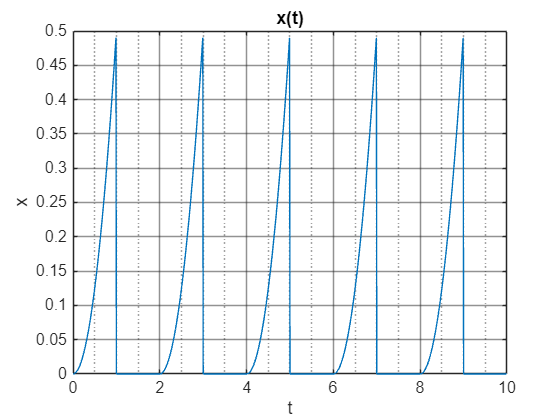

fs = 100; % sampling frequency = 100 Hz
t = 0 : 1/fs : 10 - 1/fs;
x = repmat([ (t(1:fs).^2)./2, zeros(1, fs)], [1 5]);

figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
plot(t, x);

title('x(t)')
xlim([0,10]);
ylim([0, 0.5]);   % optional to resize axis limits
xlabel('t');
ylabel('x');

box(axes1,'on');
grid(axes1,'on');
hold(axes1,'off');
% Set the remaining axes properties
set(axes1,'GridAlpha',0.5,'MinorGridAlpha',0.4,'XMinorGrid','on')

set(gca,'FontSize',12)

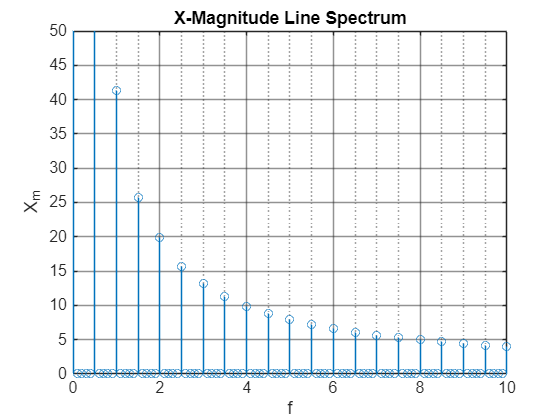

X = fft(x);
X_magnitude = abs(X);
f = (0: length(X)-1) * fs/length(X);

figure2 = figure;
axes2 = axes('Parent',figure2);
hold(axes2,'on');
stem(f, X_magnitude);

title('X-Magnitude Line Spectrum');
xlim([0,10]);
ylim([0, 50]);   % optional to resize axis limits
xlabel('f');
ylabel('X_m');

box(axes2,'on');
grid(axes2,'on');
hold(axes2,'off');

% Set the remaining axes properties
set(axes2,'GridAlpha',0.5,'MinorGridAlpha',0.4,'XMinorGrid','on')

set(gca,'FontSize',12)

### b

**List out the magnitudes of 3f, 5f, and 7f (where f is the fundamental frequency of the given signal) components.**


$$f_0 = \frac{1}{T_0}=0.5 Hz$$


### c

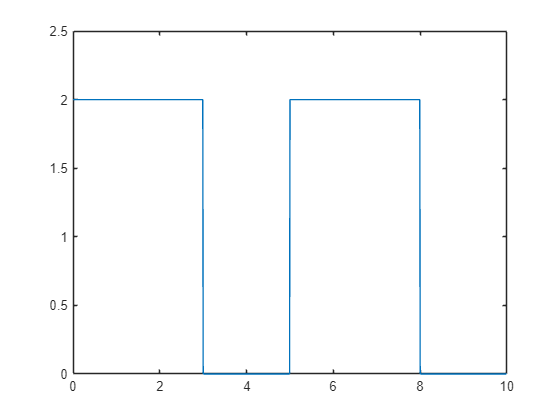

y = repmat([zeros(1, 3*fs) + 2, zeros(1, 2*fs)], [1 2]);
plot(t, y);
ylim([0, 2.5]);

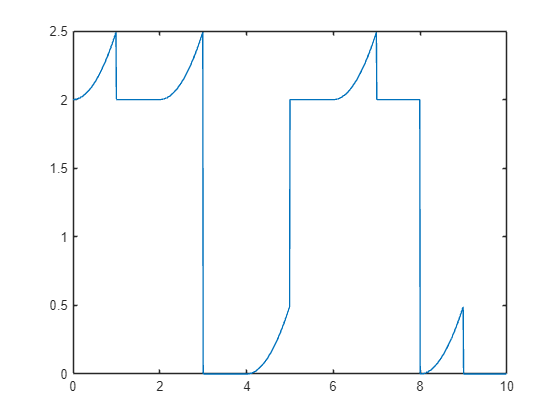

z = y + x;
plot(t, z)

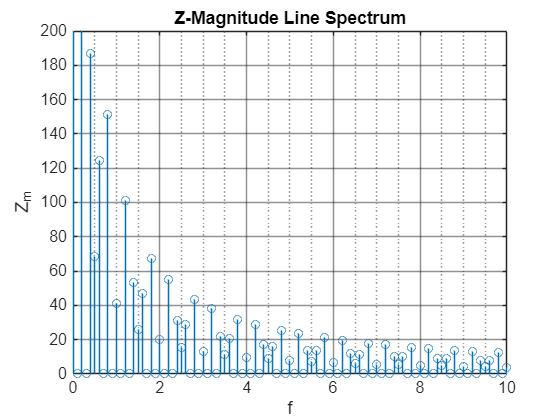

Y_magnitude = abs(fft(y));
Z_magnitude = abs(fft(z));

figure3= figure;
axes3 = axes('Parent',figure3);
hold(axes3,'on');
stem(f, Z_magnitude);

title('Z-Magnitude Line Spectrum');
xlim([0,10]);
ylim([0, 200]);   % optional to resize axis limits
xlabel('f');
ylabel('Z_m');

box(axes3,'on');
grid(axes3,'on');
hold(axes3,'off');

% Set the remaining axes properties
set(axes3,'GridAlpha',0.5,'MinorGridAlpha',0.4,'XMinorGrid','on')

set(gca,'FontSize',12)

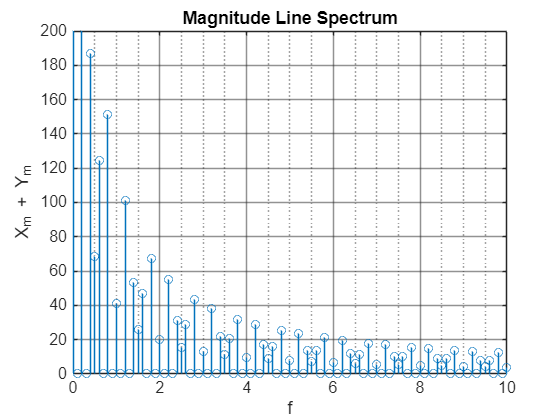

figure4= figure;
axes4 = axes('Parent',figure4);
hold(axes4,'on');
stem(f, X_magnitude + Y_magnitude);

title('Magnitude Line Spectrum');
xlim([0,10]);
ylim([0, 200]);   % optional to resize axis limits
xlabel('f');
ylabel('X_m + Y_m');

box(axes4,'on');
grid(axes4,'on');
hold(axes4,'off');

% Set the remaining axes properties
set(axes4,'GridAlpha',0.5,'MinorGridAlpha',0.4,'XMinorGrid','on')

set(gca,'FontSize',12)

## Q2

**Say **$x(t)$** is a signal with period **$T_o = 2 \, \text{s}$**, and each period has the form of **$u(t) - 2 u(t-1) + u(t-2)$**. Approximate **$x(t)$** to **$x'(t)$** with 30 harmonics and plot **$x'(t)$** using MATLAB. Also plot the magnitude line spectrum for **$x'(t)$**.**


$$x'(t) = a_0 + \sum_{k=1}^{30}\Big(a_k\cos k\omega_0t + b_k\sin k\omega_0t\Big)\\
\text{where, } \\
\hspace{4em} \omega_0 = \frac{2\pi}T_0 = \pi\\
\hspace{4em} a_0 = \frac{1}{T_0}\int_0^{T_0}x(t)dt \\
\hspace{4em} a_k = \frac{2}{T_0}\int_0^{T_0}x(t)\cos kw_0t \, dt\\
\hspace{4em} b_k = \frac{2}{T_0}\int_0^{T_0}x(t)\sin kw_0t \, dt\\$$


Let's first try to plot x(t)

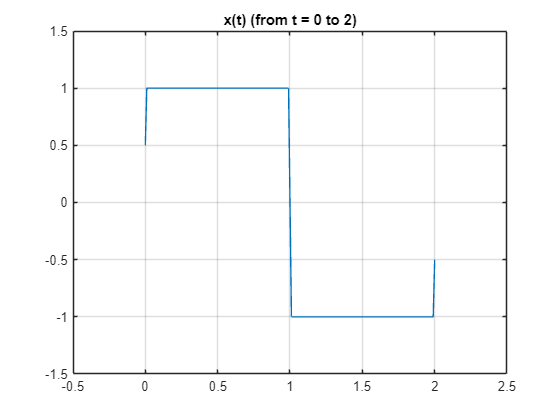

t = 0:0.01:2; % Define the time vector
u = @(t) heaviside(t); % Define the unit step function

% Define and plot the signal
x = u(t) - 2 * u(t - 1) + u(t - 2);
plot(t, x)
title('x(t) (from t = 0 to 2)');
xlim([-0.5,2.5]);
ylim([-1.5, 1.5]);
grid on;

Based on the above plot, we can say that $a_0 = 0$. Now it's a lengthy task to compute all the $a_k$ and $b_k$ by hand. So let's have matlab do it for us.


$$x'(t) = \sum_{k=1}^{30}\Big(a_k\cos k\pi t + b_k\sin k \pi t\Big)\\
\text{where, } \\
\hspace{4em} a_k = \int_0^{2}x(t)\cos k \pi t \, dt\\
\hspace{4em} b_k = \int_0^{2}x(t)\sin k \pi t \, dt\\$$


x = @(t) u(t) - 2 * u(t - 1) + u(t - 2);

a_k = @(k) integral(@(t) x(t).*cos(k*pi*t), 0, 2);
b_k = @(k) integral(@(t) x(t).*sin(k*pi*t), 0, 2);

a = zeros(1, 30);
b = zeros(1, 30);
for k = 1:30
    a(k) = a_k(k);
    b(k) = b_k(k);
end

% Create a table for a_k and b_k
disp(table((1:30)', a', b', 'VariableNames', {'k', 'a_k', 'b_k'}));

    k         a_k            b_k    
    __    ___________    ___________

     1     1.9429e-16         1.2732
     2     2.0817e-17     1.0235e-16
     3     2.2204e-16        0.42441
     4     6.9389e-18    -2.8796e-16
     5    -4.2934e-17        0.25465
     6    -1.7174e-16    -2.2204e-16
     7     4.1286e-16        0.18189
     8     1.1796e-16    -4.1633e-16
     9     3.0531e-16        0.14147
    10     1.1796e-16     4.5797e-16
    11     6.6093e-16        0.11575
    12    -3.1919e-16     3.1398e-16
    13    -8.3267e-17       0.097942
    14    -1.2143e-17    -8.3267e-17
    15     7.7369e-16       0.084883
    16     2.7582e-16     7.3726e-17
    17     1.4225e-16       0.074896
    18    -1.0061e-16    -8.4134e-17
    19     2.8623e-16       0.067013
    20     1.1276e-17    -4.1633e-17
    21    -3.4044e-17        0.06063
    22     6.6353e-16    -1.0061e-16
    23   

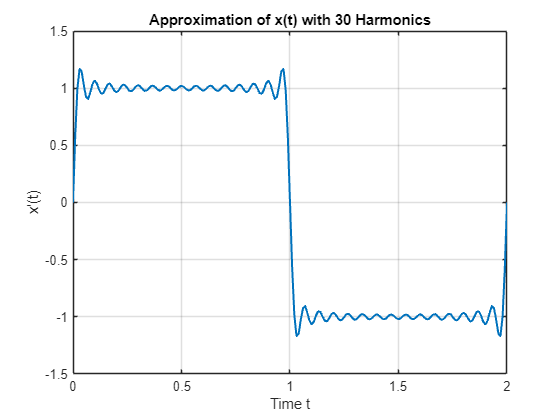

x_t_prime = zeros(size(t)); % Start with the a0 term
for k = 1:30
    x_t_prime = x_t_prime + a(k) * cos(k * pi * t) + b(k) * sin(k * pi * t);
end

figure;
plot(t, x_t_prime, 'LineWidth', 1.5);
xlabel('Time t');
ylabel('x''(t)');
title('Approximation of x(t) with 30 Harmonics');
grid on;

## Q3

**Convert the following continuous-time signals into discrete-time signals using the sampling theorem. Make sure that there is no aliasing.**

### **a**


$$x(t) = 1 + \text{sinc}(300\pi t) \\
x[n] = 1 + \text{sinc}(300\pi T_s n) \\
f_m = \frac {\omega_m} {2\pi} = 150 \\
T_s = \frac 1 f_s = \frac 1 {2f_m} = \frac 1 {2*150} = 1/300 \\
x[n] = 1 + \text{sinc}(\pi n) \hspace{2em} \text{where, } n \in Z$$


### b


$$x(t) = 1 + \cos(2000\pi t) + sin (4000 \pi t) \\
f_m = \frac {\omega_m} {2\pi} = 2000 \\
T_s = \frac 1 {2f_m} = \frac 1 {4000} \\
x[n] = x(nT_s) = 1 + \cos\Big(\pi \frac n 2\Big) + \sin(\pi n)  \hspace{2em} \text{where, } n \in Z$$


### c


$$x(t) = 10\sin 40\pi t \cos 300\pi t = 5 \sin 340\pi t - 5 \sin 260\pi t \\
f_m = \frac {340\pi} {2\pi} = 170 \\
T_s = \frac 1 {2*170} = \frac 1 {340} \\
x[n] = x(nT_s) = 10 \sin \frac 2 {17} \pi n \cos \frac {15} {17}\pi n = 5 \sin \pi n - 5 \sin \frac{13}{17}\pi n \\
 \hspace{2em} \text{where, } n \in Z$$


## Q4

**Find out the FT of the given signal in MATLAB without using the FFT built-in function and plot the phase and magnitude graph for the given signal. Compare your results with the built-in function FFT.**


$$x = \sin 30\pi t + \sin 80\pi t \\
X(\omega) = \sum_0^T x(t)e^{j\omega t}$$


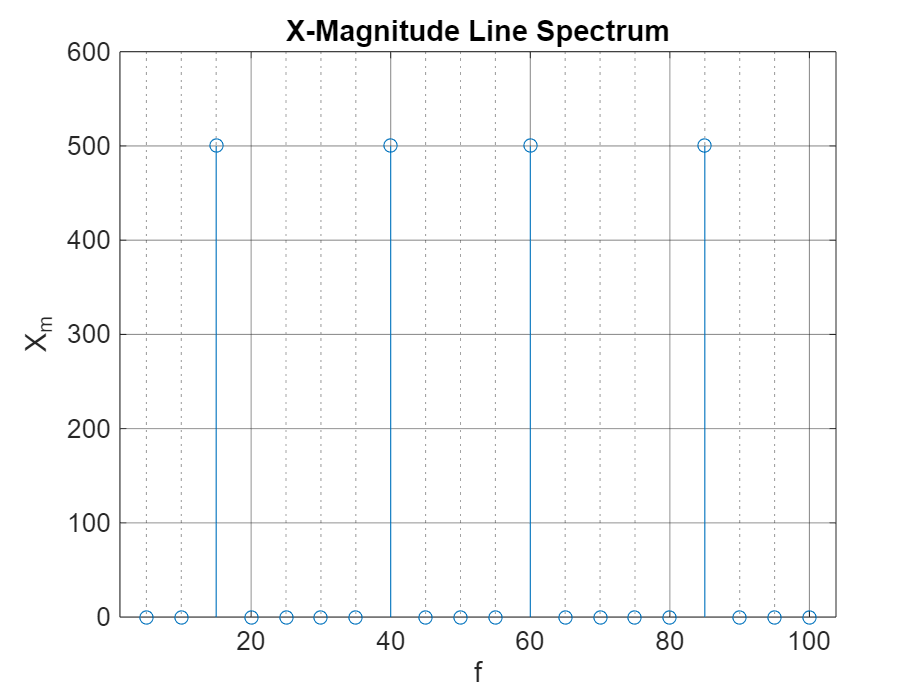

t = 0:1/100:10-1/100; % Time vector
x = sin(2*pi*15*t) + sin(2*pi*40*t); % Signal

X = zeros([1 20]);
omega_0 = 10*pi;
for k = 1:20
    Angle = k * omega_0 * t;
    X(k) = x * (cos(Angle) + 1i*sin(Angle))';
end

f = 5:5:100;

figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
stem(f, abs(X))
title('X-Magnitude Line Spectrum');
% xlim([0,10]);
% ylim([0, 50]);   % optional to resize axis limits
xlabel('f');
ylabel('X_m');

box(axes1,'on');
grid(axes1,'on');
hold(axes1,'off');

% Set the remaining axes properties
set(axes1,'GridAlpha',0.5,'MinorGridAlpha',0.4,'XMinorGrid','on')

set(gca,'FontSize',12)

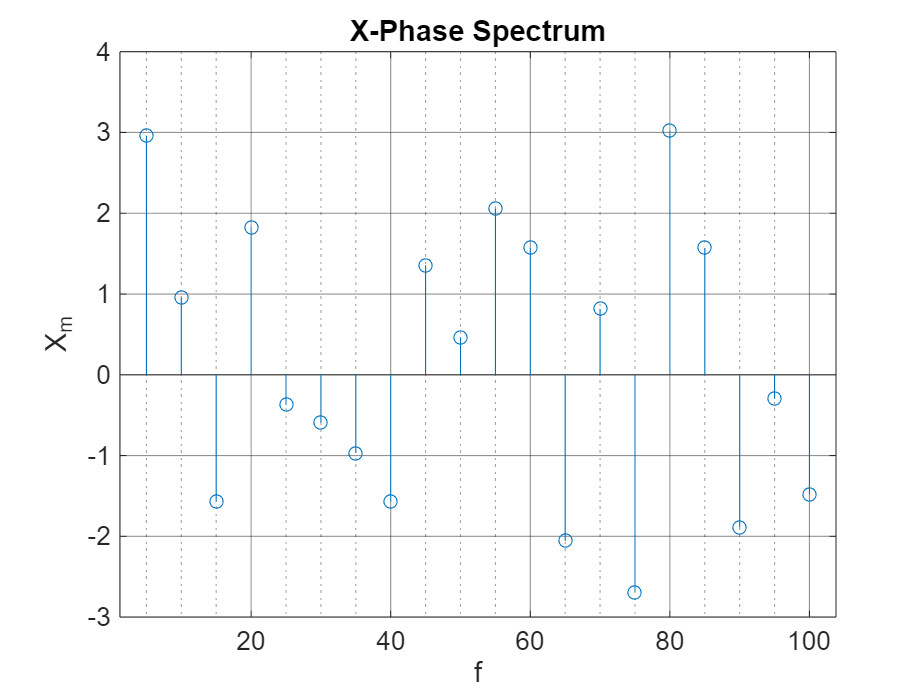

figure2 = figure;
axes2 = axes('Parent',figure2);
hold(axes2,'on');
stem(f, angle(X))
title('X-Phase Spectrum');
% xlim([0,10]);
% ylim([0, 50]);   % optional to resize axis limits
xlabel('f');
ylabel('X_m');

box(axes2,'on');
grid(axes2,'on');
hold(axes2,'off');

% Set the remaining axes properties
set(axes2,'GridAlpha',0.5,'MinorGridAlpha',0.4,'XMinorGrid','on')

set(gca,'FontSize',12)

## Q5

**Consider the following signal:**


$$x(t) = r(t+1)-2r(t)+r(t-1) \\
y(t) = \frac {d x} {dt}$$


### a

**Obtain **$X(\Omega)$** and **$Y(\Omega)$**, plot their magnitude and phase spectrums, and comment whether **$X(\Omega)$** and **$Y(\Omega)$** are real or imaginary.**


$$\begin{array}{rcl}

\text X(\Omega) &=& \int_{-\infty}^{+\infty}x(t)e^{j\Omega t}dt \\
&=& \int_{- \frac 3 2}^{- \frac 1 2} e^{j\Omega t} dt + \int_{\frac 1 2}^{\frac 3 2}e^{j\Omega t}dt - \int_{-\frac 1 2}^{\frac 1 2} e^{j\Omega t}dt \\
&=& \frac 1 {j\Omega}\big(e^{3/2j\Omega} + 2e^{-1/2j\Omega} - 2 e^{1/2j\Omega} - e^{-3/2j\Omega}\big) \\

\end{array}$$
 
$$\begin{array}{rcl}
\text Y(\Omega) &=& \int_{-\infty}^{+\infty}\frac{dx}{dt}e^{j\Omega t}dt \\ 
&=& e^{j\Omega t}x(t) |_{-\infty}^{+\infty} - j\Omega \int_{-\infty}^{+\infty}x(t)e^{j\Omega t}dt \\
&=& -j\Omega * \text X(\Omega)
\end{array}$$


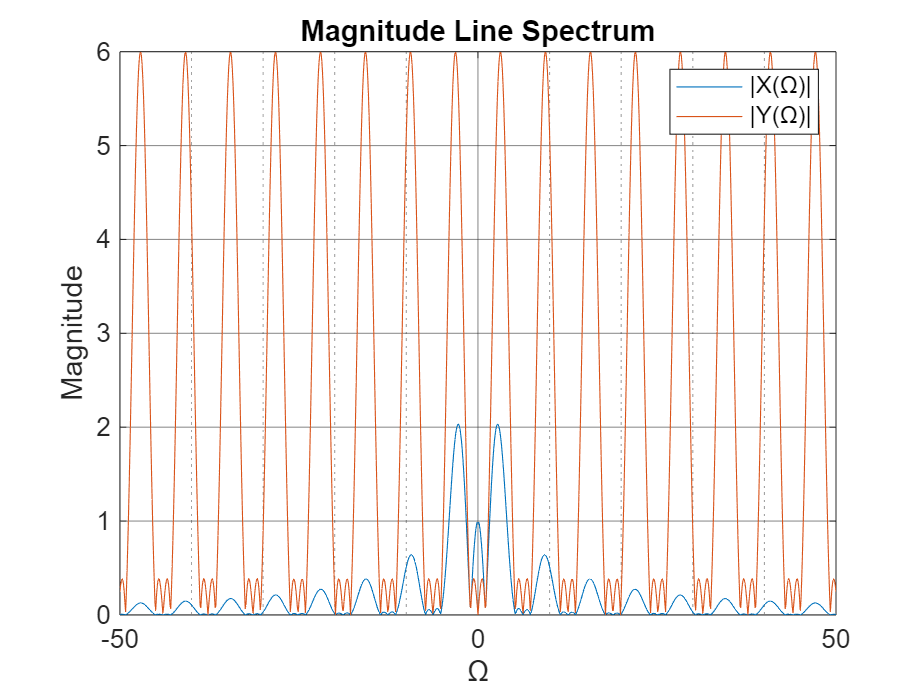

omega = -50:0.1:50;
Y = - exp(1.5i .* omega) - 2 * exp(-0.5i .* omega) + 2 * exp(0.5i .* omega) + exp(-1.5i .* omega);
X = Y./ (-1i * omega);

figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
plot(omega, abs(X), 'DisplayName', '|X(\Omega)|')
plot(omega, abs(Y), 'DisplayName', '|Y(\Omega)|')
title('Magnitude Line Spectrum');
% xlim([0,10]);
% ylim([0, 50]);   % optional to resize axis limits
xlabel('\Omega');
ylabel('Magnitude');
legend

box(axes1,'on');
grid(axes1,'on');
hold(axes1,'off');

% Set the remaining axes properties
set(axes1,'GridAlpha',0.5,'MinorGridAlpha',0.4,'XMinorGrid','on')

set(gca,'FontSize',12)

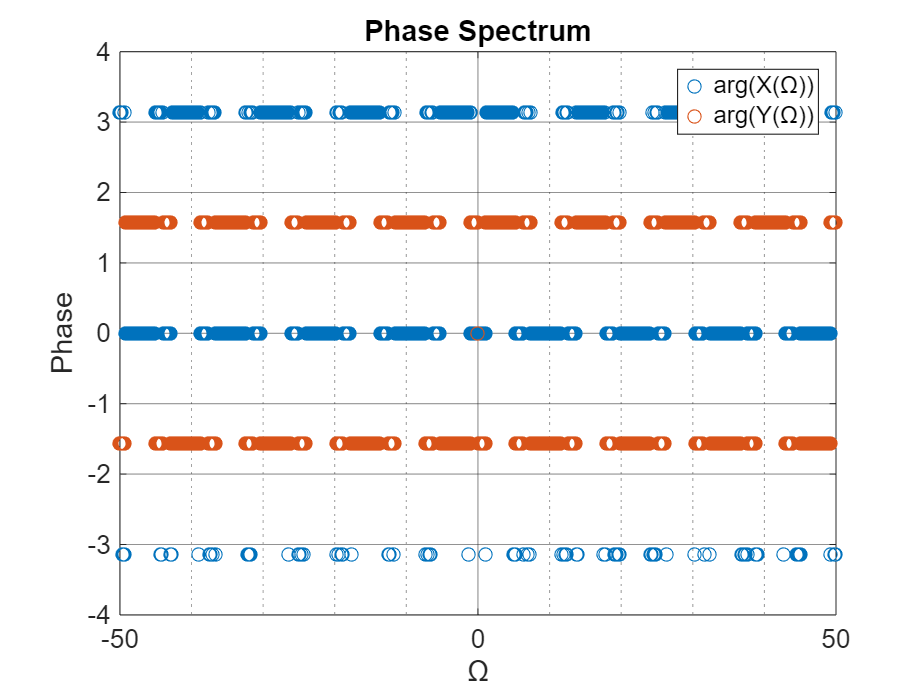


figure2 = figure;
axes2 = axes('Parent',figure2);
hold(axes2,'on');
scatter(omega, angle(X), 'DisplayName', 'arg(X(\Omega))')
scatter(omega, angle(Y), 'DisplayName', 'arg(Y(\Omega))')
title('Phase Spectrum');
% xlim([0,10]);
% ylim([0, 50]);   % optional to resize axis limits
xlabel('\Omega');
ylabel('Phase');
legend

box(axes2,'on');
grid(axes2,'on');
hold(axes2,'off');

% Set the remaining axes properties
set(axes2,'GridAlpha',0.5,'MinorGridAlpha',0.4,'XMinorGrid','on')

set(gca,'FontSize',12)

We could already tell from the derived equations that $X(\Omega)$ and $Y(\Omega)$ were $90^o$ out of phase. Based on the above phase spectrum now, it is clear that the phase of $X(\Omega)$ is either $0, +\pi, \text{or } -\pi$. Thus $X(\Omega)$ is real, and $Y(\Omega)$ is imaginary.

### b

**Determine from the above spectra which of these two signals are smoother. Use MATLAB integration function int to find the fourier transforms. Plot **$20 \log_{10}| Y(\Omega)|$** and **$20 \log_{10}| X(\Omega)|$** and decide. Would you say in general that computing the derivative of a signal generates high frequencies or possible discontinuities.**

We can easily conclude based on the magnitude line spectra that $x(t)$ is much smoother than $y(t)$. The reason being that magnitude of high frequencies in it's spectra is significantly lower due to $X(\Omega)$ being a decaying function of $\Omega$. It implies components of $x(t)$ are mainly low frequency sine and cosine waves while $y(t)$ has a lot of high frequency components. Thus, $y(t)$ would fluctuate a lot more than $x(t)$ and would seem noisy/less smooth in comparison to x(t).

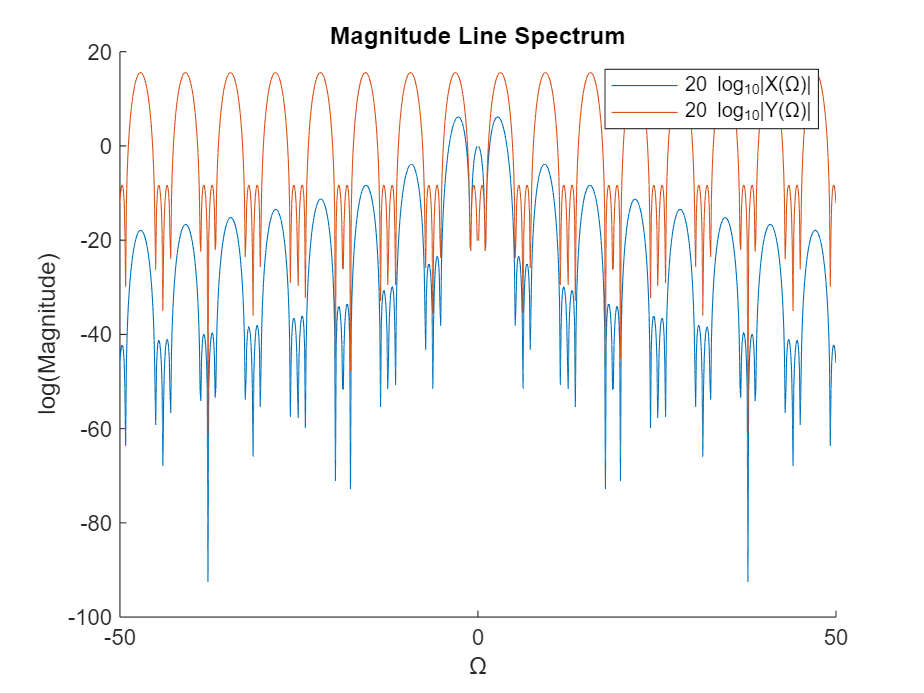

figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
plot(omega, 20.*log10(abs(X)), 'DisplayName', '20 log_{10}|X(\Omega)|')
plot(omega, 20.*log10(abs(Y)), 'DisplayName', '20 log_{10}|Y(\Omega)|')
title('Magnitude Line Spectrum');
% xlim([0,10]);
% ylim([0, 50]);   % optional to resize axis limits
xlabel('\Omega');
ylabel('log(Magnitude)');
legend